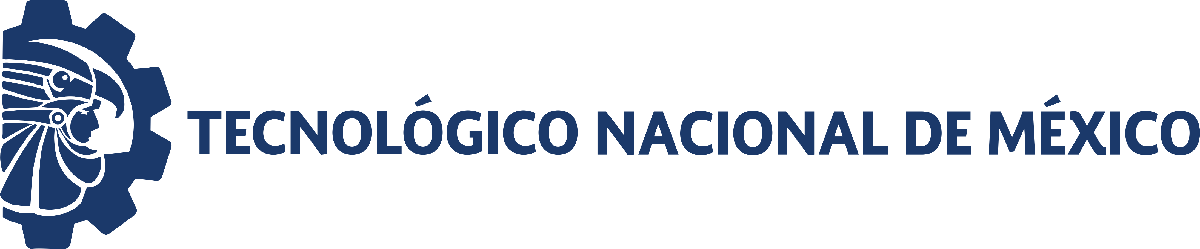                                 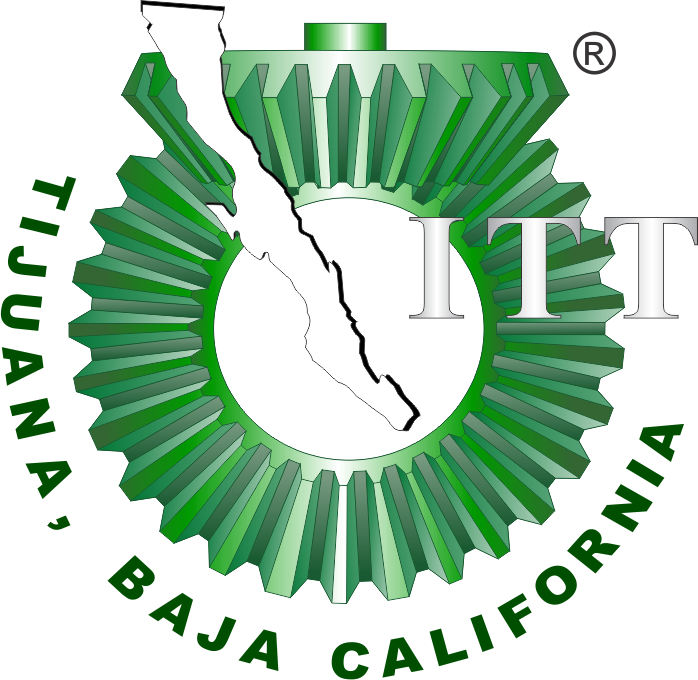

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Práctica 2: Sistema presa-depredador de Lotka Volterra

## Información general

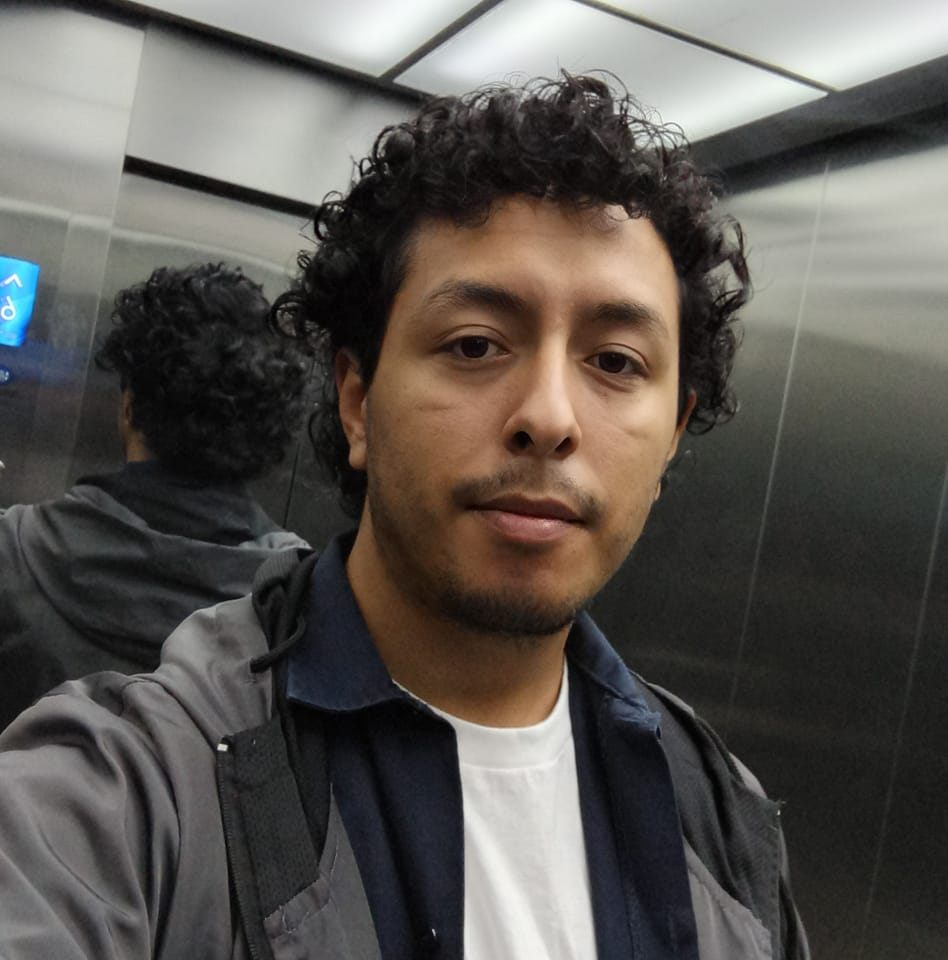

Nombre del alumno: **Cipriano Camacho Mario Tolentino**

Número de control: **20211961**

Correo institucional: **l20211961@tectijuana.edu.mx**

Carrera: **Ingenieria Biomedica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

**Objetivo:** Solucionar las ecuaciones de Lotka-Volterra para estudiar e ilustrar su dinamica en series de tiempo y el plano de fase. El sistema presa-predador se formula mediante las siguientes dos EDOs de primer orden,


$$\begin{array}{l}
\dot{x} =\alpha x-\beta \mathrm{xy}\\
\dot{y} =\delta \mathrm{xy}-\gamma y
\end{array}$$


con los valores de los parametros $\alpha =0\ldotp 5$, $\beta =0\ldotp 01$, $\delta =0\ldotp 005$ y $\gamma =0\ldotp 2$ y las coordenadas iniciales $x\left(0\right)=75$ y $y\left(0\right)=75$.

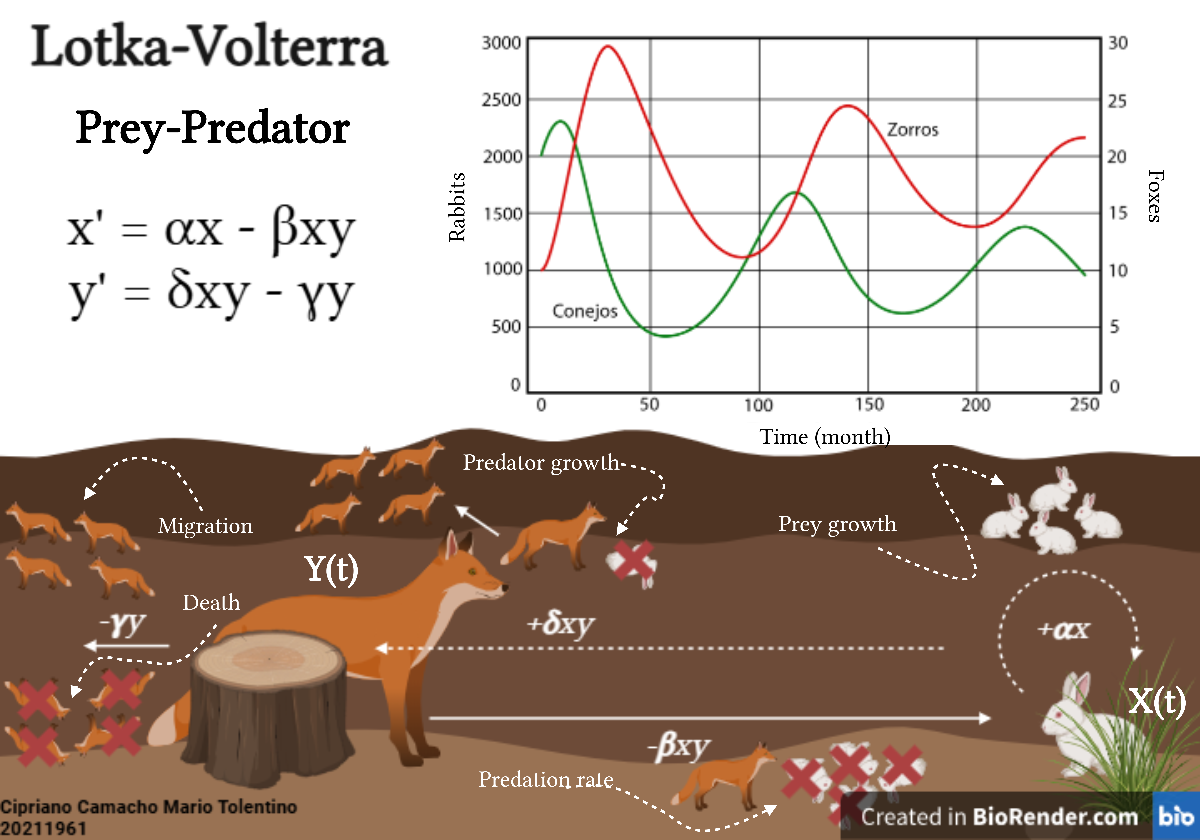

Figure: Fowes encounter rabbits: this encounter results in predation by the rabbits [negative feedback] and the foxes grow [positive feedback]. Adittionaly, the foxes die [exponential decay] and the rabbits reproduce [exponential growth].

## Simulation data

%Datos de la simulación
clc; clear; close all; warning('off','all')
c1 = [0.11, 0.30, 0.85]; c2 = [0.20, 0.60, 0.30];
c3 = [0.85, 0.25, 0.30]; c4 = [0.95, 0.80, 0.20]; 

## Parameters and initial condition

alpha = 0.5; beta = 0.01; delta = 0.001; gamma = 0.2;

P = [alpha,beta,delta,gamma];
x0 = 75; y0 = 75; tend = 100;

## Solution by Euler's method

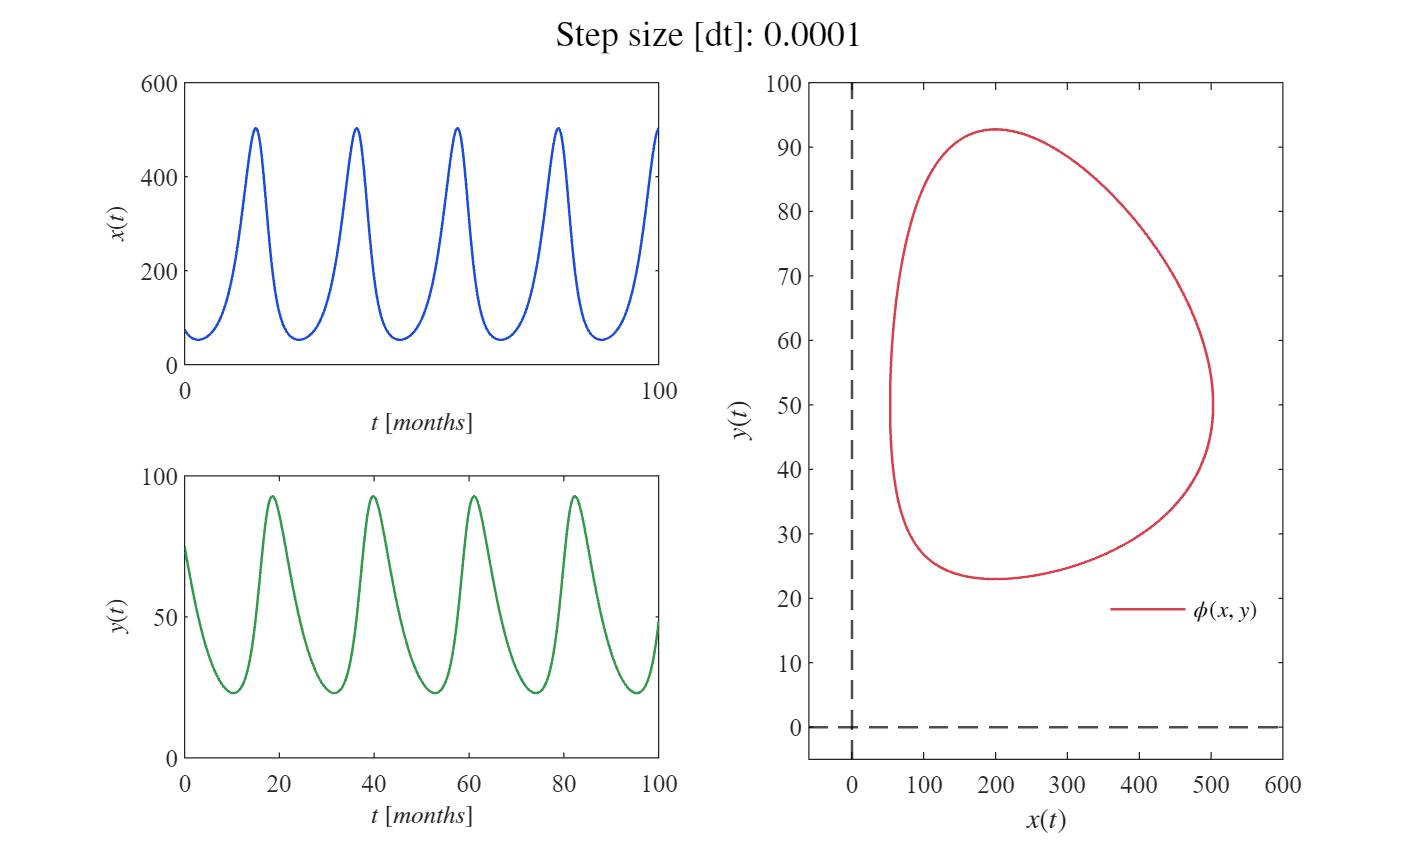

%dt = [2,1,0.5,0.25,1E-1,1E-2,1E-3,1E-4,1E-5,1E-6];
dt = 1E-4;
for i = 1: numel(dt)
    [t,x,y] = sys_Euler(x0,y0,dt(i),tend,P);
    plotEDOs(t,x,y,P,dt(i));
    %exportgraphics(gcf,['Lotka-Volterra Euler ', num2str(dt(i)),'.pdf'],'ContentType','Vector')
end

## Solution by Heun's method

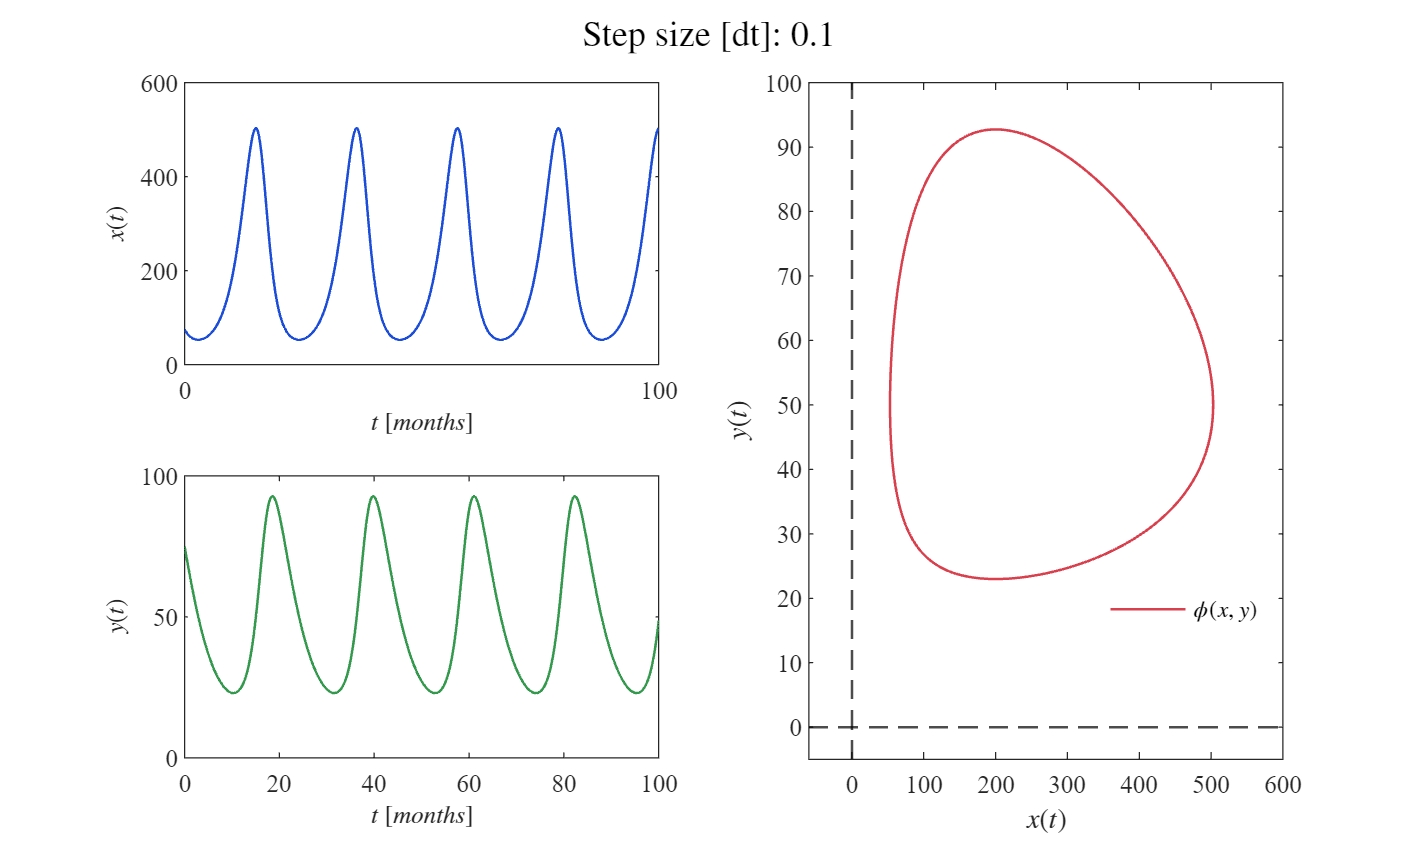

%dt = [2,1,0.5,0.25,1E-1];%,1E-2,1E-3,1E-4,1E-5,1E-6];
dt = 0.1;
for i = 1: numel(dt)
    [t,x,y] = sys_Heun(x0,y0,dt(i),tend,P);
    plotEDOs(t,x,y,P,dt(i));
    %exportgraphics(gcf,['Lotka-Volterra Heun ', num2str(dt(i)),'.pdf'],'ContentType','Vector')
end

## Simulink

file = 'system';
sim(file);
parameters.StopTime = '100';

### Solution by ode15s [Stiff solver]

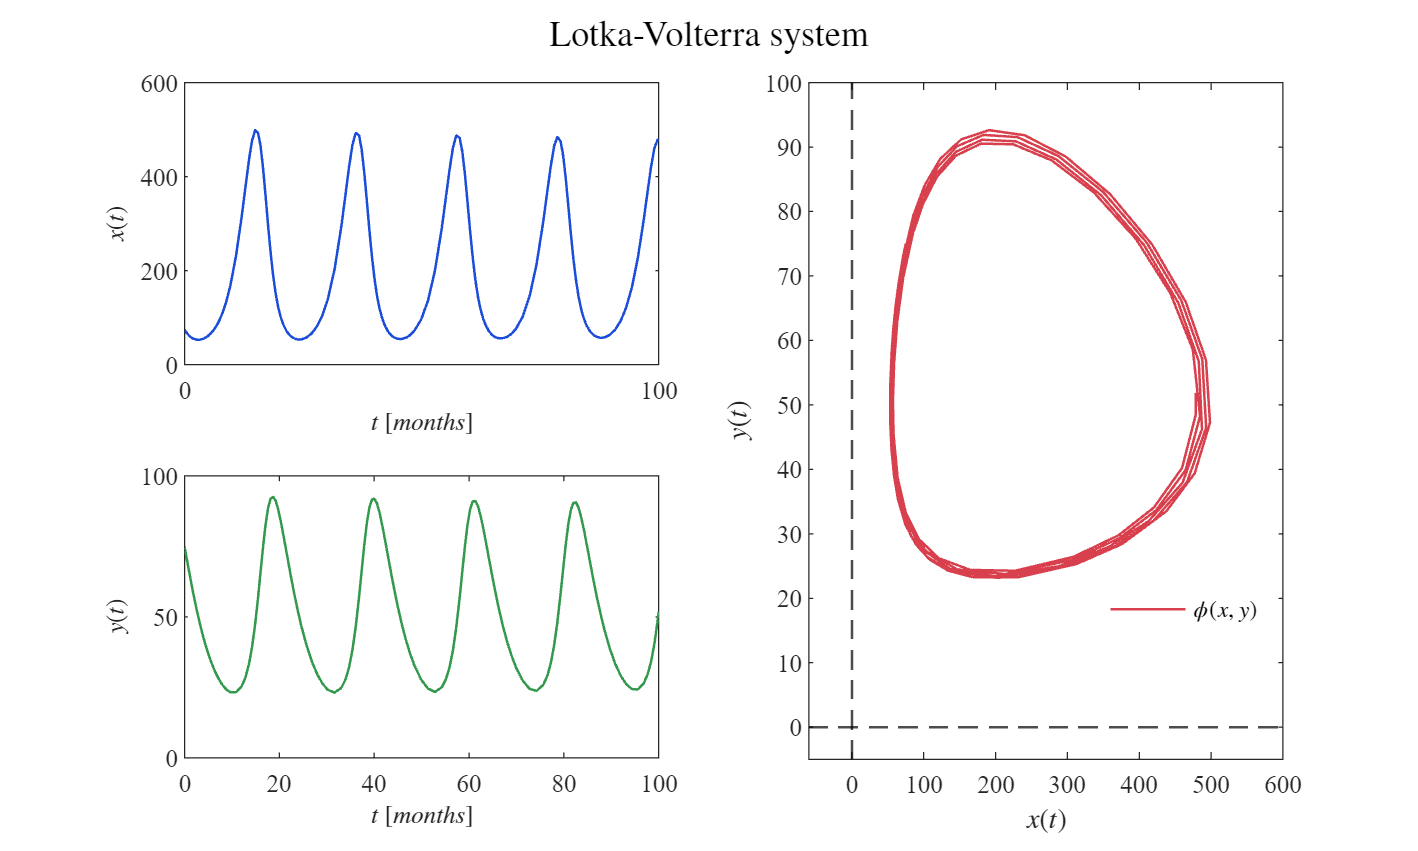

parameters.Solver = 'ode15s';
s15s = sim(file,parameters);
plotEDOs(s15s.t,s15s.x,s15s.y,P,0);
exportgraphics(gcf,'Lotka-Volterra ode15s.pdf','ContentType','Vector')

### Solution by ode23s [Stiff Solvers]

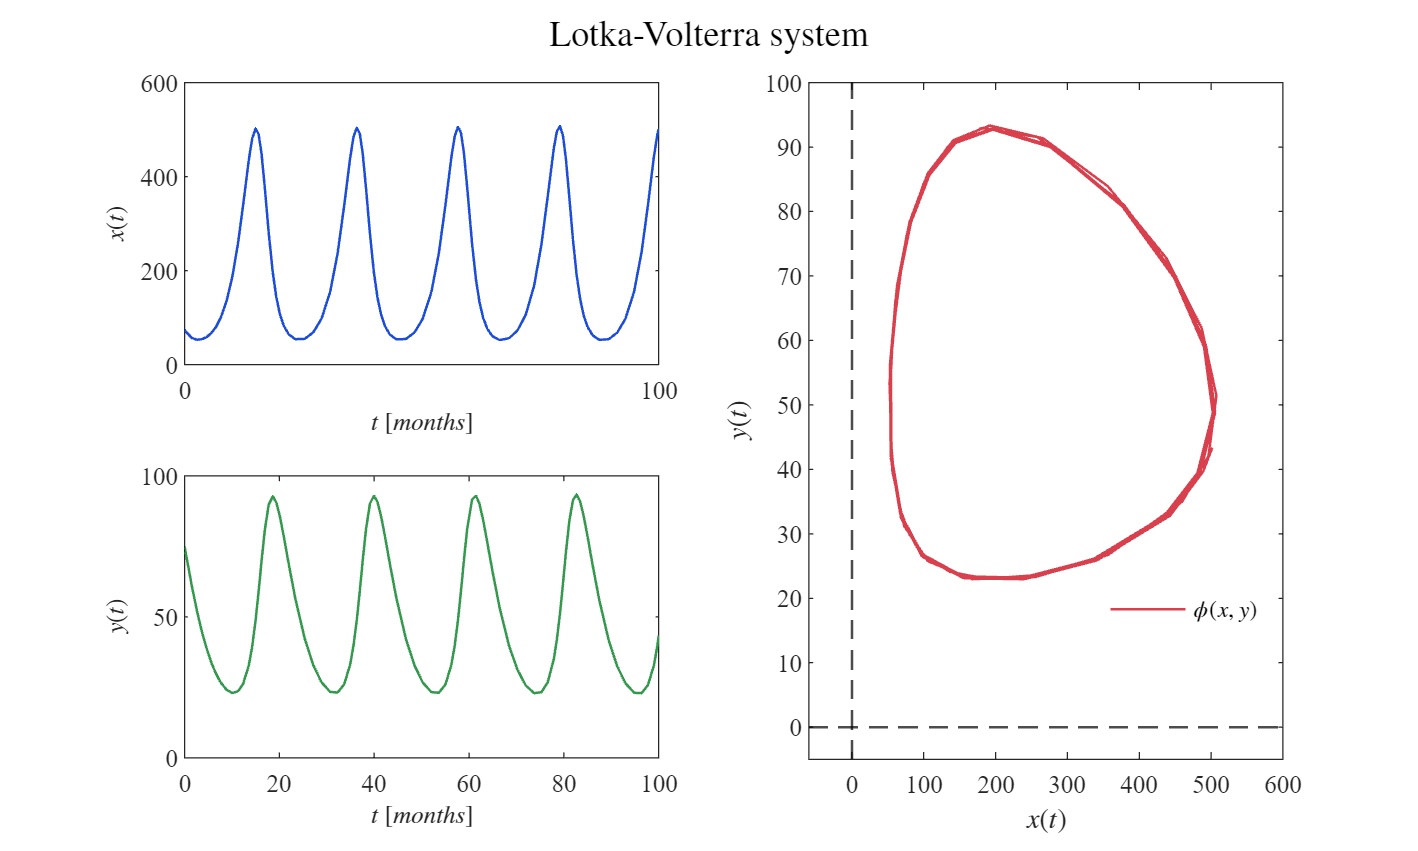

parameters.Solver = 'ode23s';
s23s = sim(file,parameters);
plotEDOs(s23s.t,s23s.x,s23s.y,P,0)
exportgraphics(gcf,'Lotka-Volterra ode23s.pdf','ContentType','Vector')

### Solution by ode23t [Stiff Solvers]

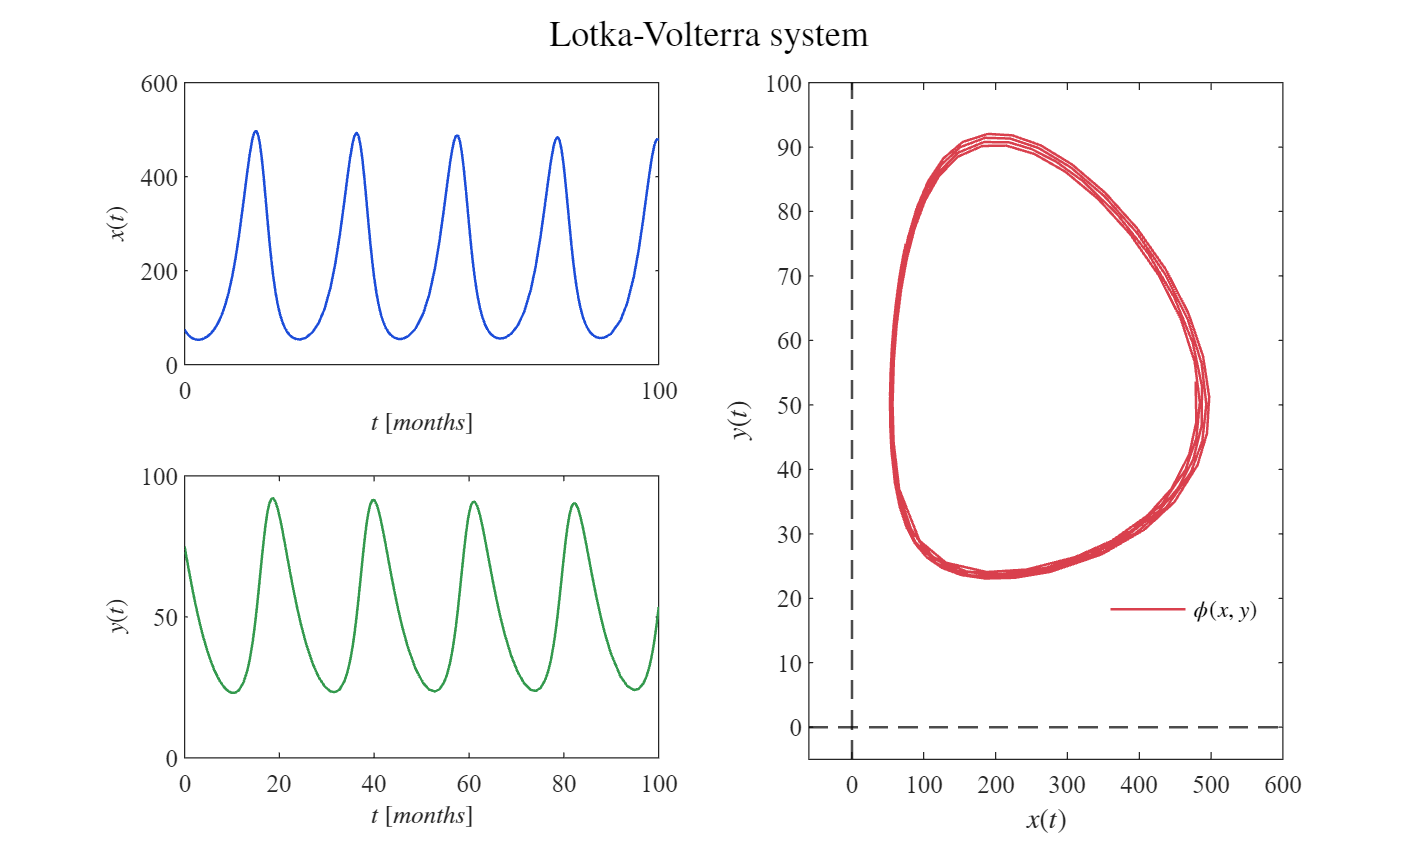

parameters.Solver = 'ode23t';
s23t = sim(file,parameters);
plotEDOs(s23t.t,s23t.x,s23t.y,P,0)
exportgraphics(gcf,'Lotka-Volterra ode23t.pdf','ContentType','Vector')

### Solution by ode23tb [Stiff Solvers]

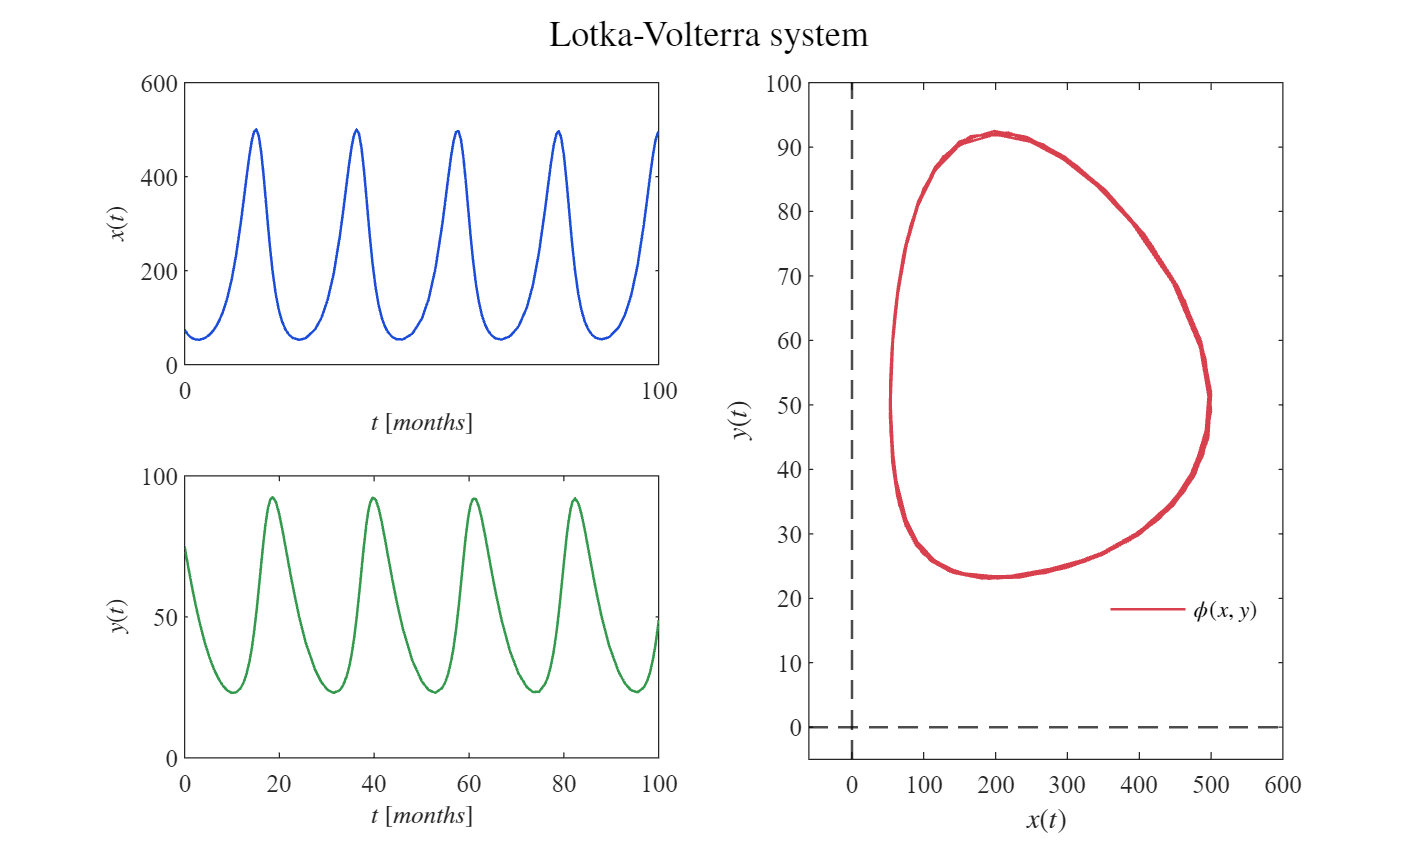

parameters.Solver = 'ode23tb';
s23tb = sim(file,parameters);
plotEDOs(s23tb.t,s23tb.x,s23tb.y,P,0)
exportgraphics(gcf,'Lotka-Volterra ode23tb.pdf','ContentType','Vector')

### Solution by ode45 [Nonstiff Solvers]

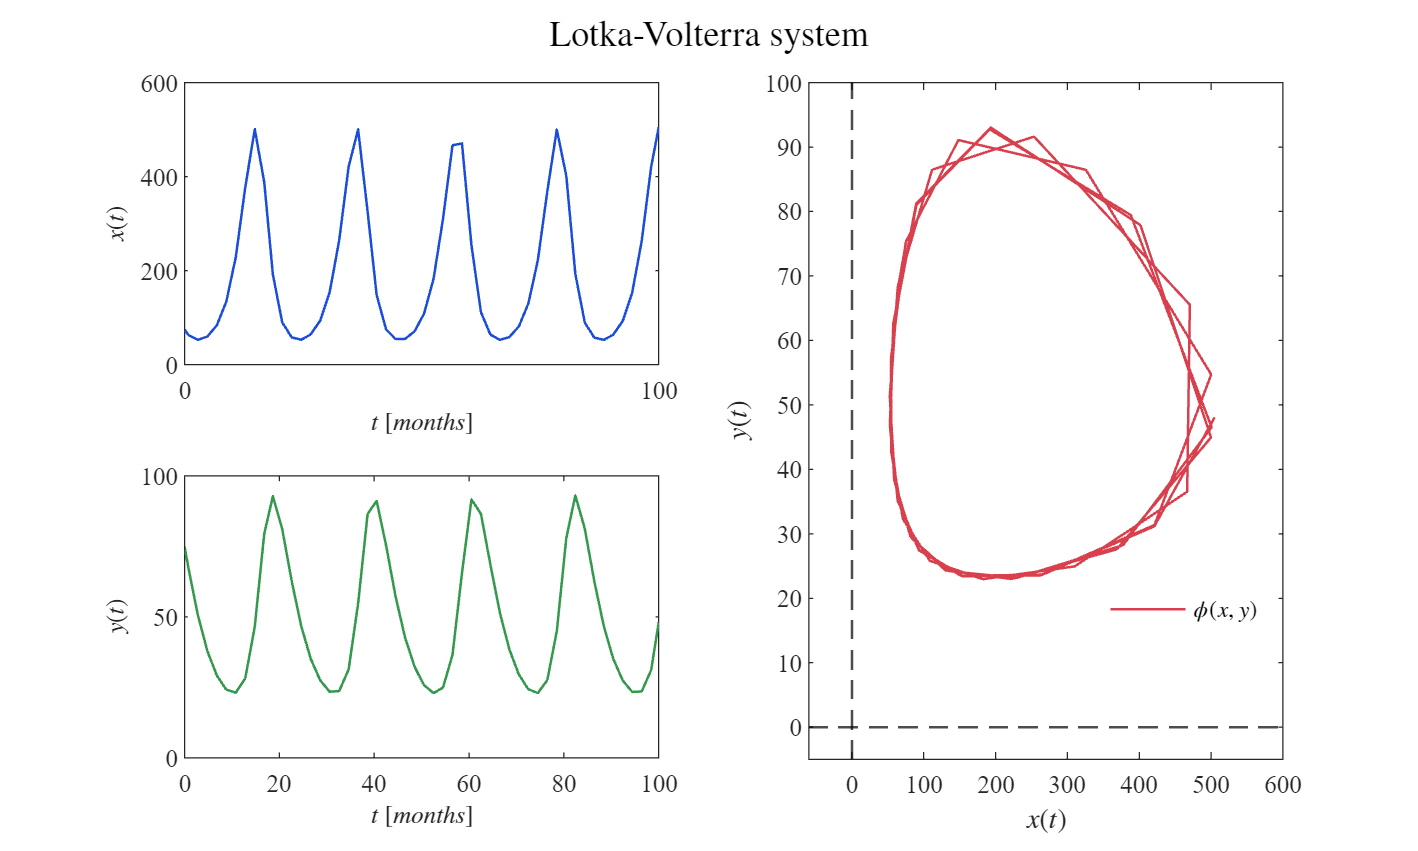

parameters.Solver = 'ode45';
s45 = sim(file,parameters);
plotEDOs(s45.t,s45.x,s45.y,P,0)
exportgraphics(gcf,'Lotka-Volterra ode45.pdf','ContentType','Vector')

### Solution by ode23 [Nonstiff Solvers]

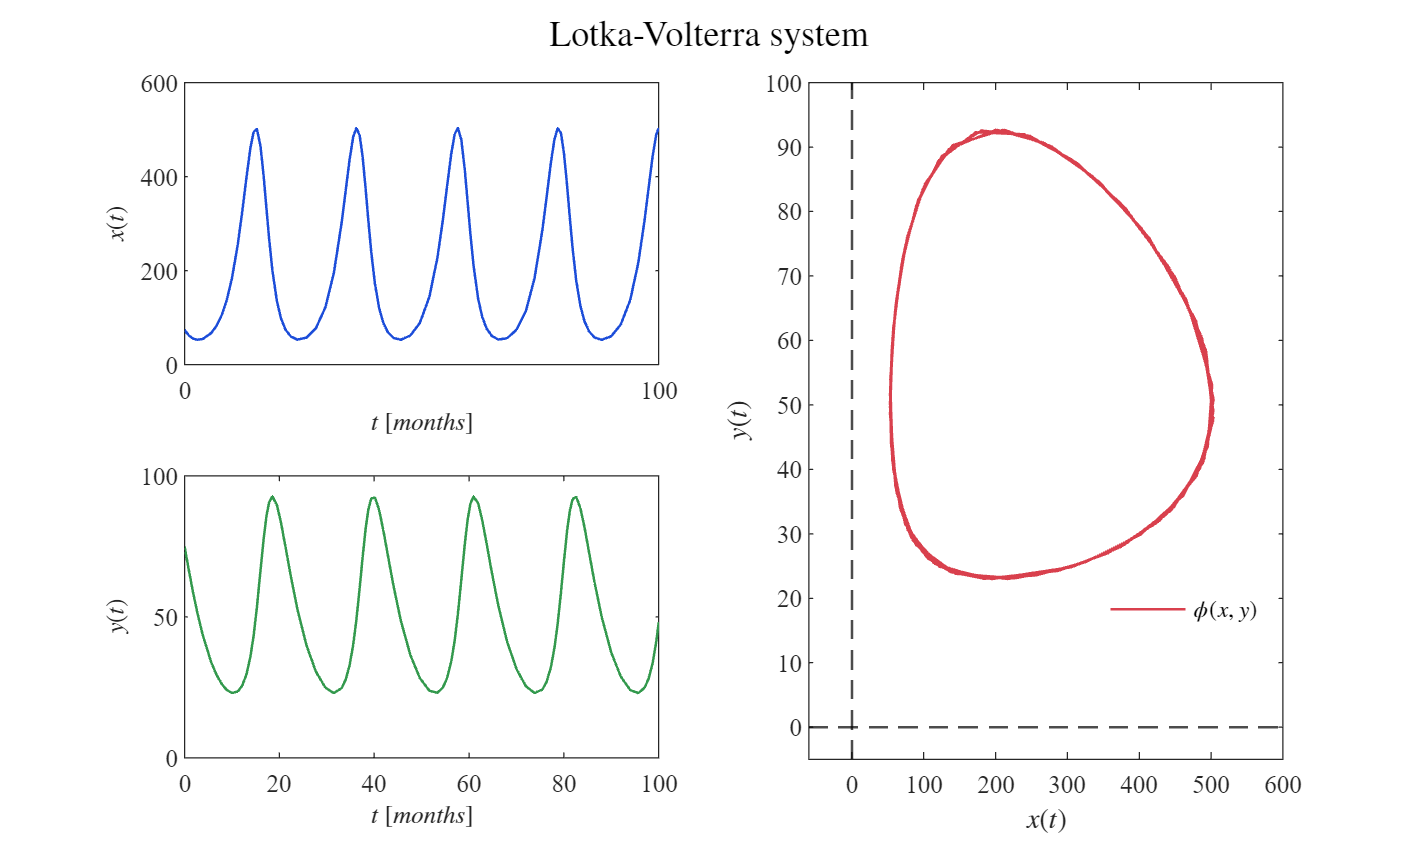

parameters.Solver = 'ode23';
s23 = sim(file,parameters);
plotEDOs(s23.t,s23.x,s23.y,P,0)
exportgraphics(gcf,'Lotka-Volterra ode23.pdf','ContentType','Vector')

### Solution by ode113 [Nonstiff Solvers]

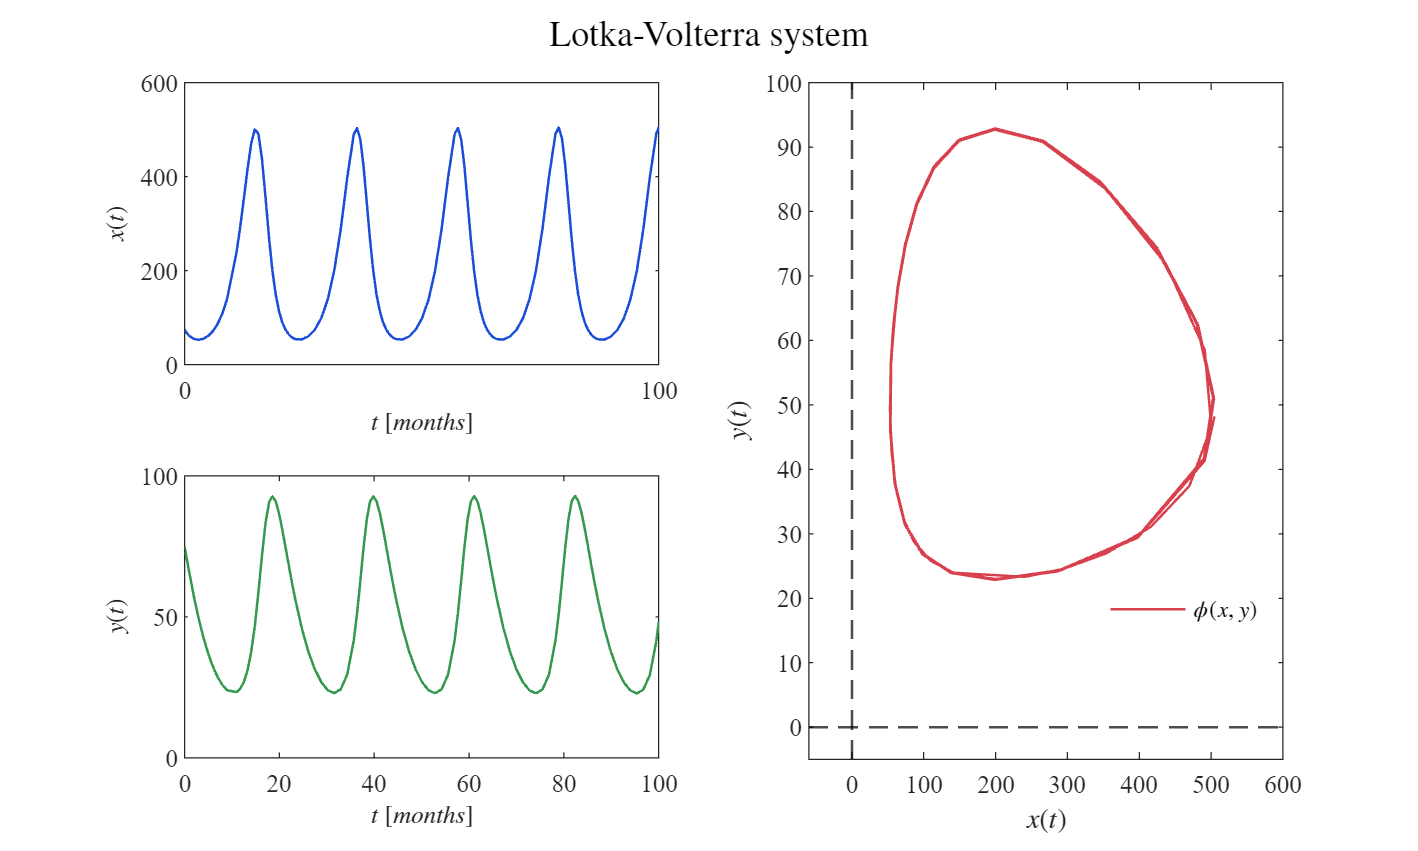

parameters.Solver = 'ode113';
s113 = sim(file,parameters);
plotEDOs(s113.t,s113.x,s113.y,P,0)
exportgraphics(gcf,'Lotka-Volterra ode113.pdf','ContentType','Vector')

Con base las simulaciones numéricas y considerando que la solución del sistema de Lotka-Volterra no requiere pasos de integración muy pequeños para métodos como el de Heun, se concluye que dicho sistema no es rígido (*nonstiff*). Además, al utilizar los solucionadores de MATLAB, una de las mejores aproximaciones a la solución se obtuvo con el método **ode23 **el cual es un "*nonstiff solver"*. Esto sugiere que el sistema de Lotka-Volterra no presenta las características de rigidez que requieren el uso de métodos implícitos o solucionadores especializados en sistemas rígidos.

Referencia: M. Cleve, “Stiff Differential Equations,” *Mathworks.com*, 2003. https://la.mathworks.com/company/technical-articles/stiff-differential-equations.html (accessed Feb. 24, 2025).

## Equilibrium points and Jacobian matrix

clear; close all; clc
syms x y alpha beta delta gamma
dx = alpha*x - beta*x*y;
dy = delta*x*y - gamma*y;
J = jacobian([dx,dy],[x,y]);
fprintf('Jacobian matrix of the Lotka-Volterra system: '); disp(J)

Jacobian matrix of the Lotka-Volterra system: 

$$\left(\begin{array}{cc} \alpha -\beta \,y & -\beta \,x\\ \delta \,y & \delta \,x-\gamma \end{array}\right)$$

dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;
edos = solve([dx,dy],[x,y]);
fprintf(['the Lotka-Volterra system has ', num2str(length(edos.x)), ' equilibrium points.'])

the Lotka-Volterra system has 2 equilibrium points.

X0 = edos.x(1); Y0 = edos.y(1);
X1 = edos.x(2); Y1 = edos.y(2);
syms x0 y0 x1 y1
fprintf('Equilibrium points of the Lotka-Volterra system: '); disp([x0,y0,X0,Y0]); disp ([x1,y1,X1,Y1])

Equilibrium points of the Lotka-Volterra system: 

$$\left(\begin{array}{cccc} x_{0} & y_{0} & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{1} & y_{1} & \frac{\gamma }{\delta } & \frac{\alpha }{\beta } \end{array}\right)$$

clear alpha beta delta gamma
alpha = 0.5; beta = 0.01; delta = 0.001; gamma = 0.2;
disp('(x0,y0) = (0,0)'); disp(['(x1,y1) = (', num2str(gamma/delta),',', num2str(alpha/beta),')'])

(x0,y0) = (0,0)
(x1,y1) = (200,50)


## Local stability

clc; clear; 
alpha = 0.5; beta = 0.01; delta = 0.001; gamma = 0.2;
syms x y
dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;
edos = solve([dx,dy],[x,y]);
x0 = double(edos.x(1)); y0 = double(edos.y(1));
x1 = double(edos.x(2)); y1 = double(edos.y(2));
clear x y
x = [x0; x1]; y = [y0; y1];
var = {'(x0,y0)';'(x1,y1)'};
Equilibria = table(x,y,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye'};
fprintf('Equilibrium points of the Lotka-Volterra system: \n'); disp(Equilibria)

Equilibrium points of the Lotka-Volterra system: 
               xe     ye
               ___    __

    (x0,y0)      0     0
    (x1,y1)    200    50



L = zeros(length(x),length(x));
for i = 1: length(x)
    J = [alpha - beta*y(i),         -beta*x(i);
                delta*y(i), delta*x(i) - gamma];
    L(i,:) = eig(J);
end
L1 = L(:,1); L2 = L(:,2);
Lambdas = table(L1,L2,'RowNames',var);
disp('Eigen vales of the Jacobian matrix evaluatedes at each equilibrium point:' ); disp(Lambdas)

Eigen vales of the Jacobian matrix evaluatedes at each equilibrium point:
                    L1               L2     
               _____________    ____________

    (x0,y0)    -0.2+0i          0.5+0i      
    (x1,y1)       0+0.31623i      0-0.31623i



Para $\left(x_0 ,y_0 \right)$, los valores propios $\left(\lambda_1 ,\lambda_2 \right)\;$  son reales y de signo opuesto. Esto indica que el punto es inestable, ya que corresponde al tercer caso, denominado **nodo silla**. En esta configuración, casi todas las trayectorias divergen hacia el infinito debido a que uno de los valores propios es positivo.

Para $\left(x_0 ,y_0 \right)$, los valores propios $\left(\lambda_1 ,\lambda_2 \right)\;$ son complejos conjugados, lo que representa un caso marginal de **centro**, dado que la parte real es cero. Como consecuencia, esperamos que las trayectorias sean periódicas alrededor del punto de equilibrio. Esto coincide con el **caso 5 de valores propios complejos conjugados**, conocido como **nodo centro**, donde las trayectorias forman un elipsoide con el origen en su centro.

## Equilibrium points

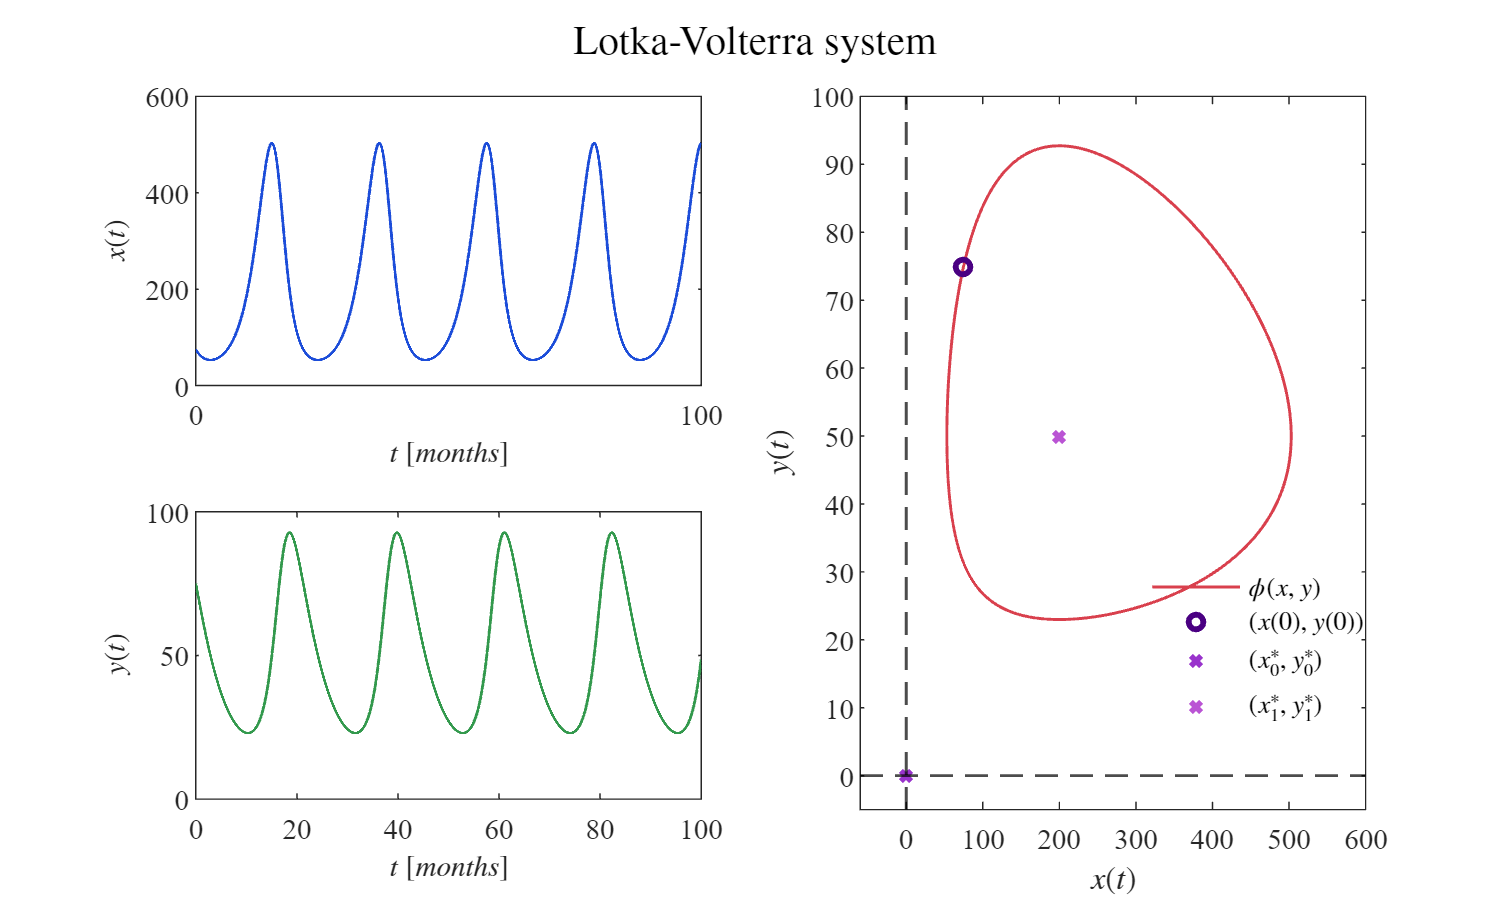

alpha = 0.5; beta = 0.01; delta = 0.001; gamma = 0.2;
P = [alpha,beta,delta,gamma];
x0 = 75; y0 = 75; tend = 100;
dt = 1E-2;
[t,x,y] = sys_Heun(x0,y0,dt,tend,P);
plotEDOs(t,x,y,P,dt); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf, 'Lotka-Volterra Equilibria.pdf','ContentType','vector')

## Data fitting

clc; clear; close all

## Raw data

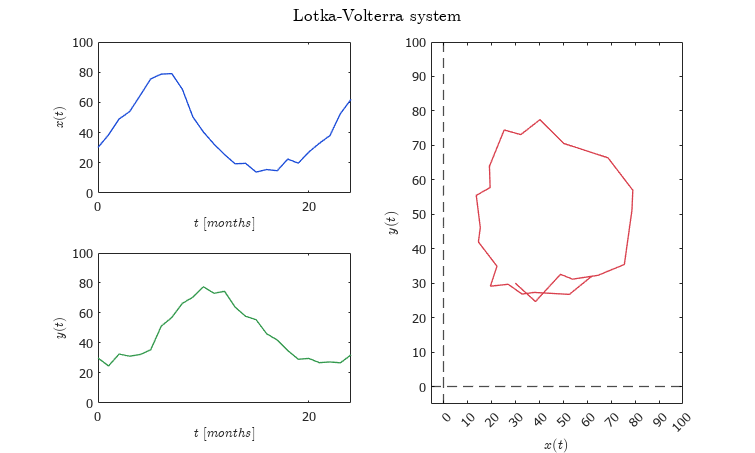

sys = readmatrix('data.csv');
to = sys(:,1); xo = sys(:,2); yo = sys(:,3);
alpha = 0.5; beta = 0.01; delta = 0.001; gamma = 0.2;
P = [alpha,beta,delta,gamma];
plotEDOsfit(to,xo,yo,P,0); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf, 'Data fitting Lotka-Volterra.pdf','ContentType','vector')

## Smooth data

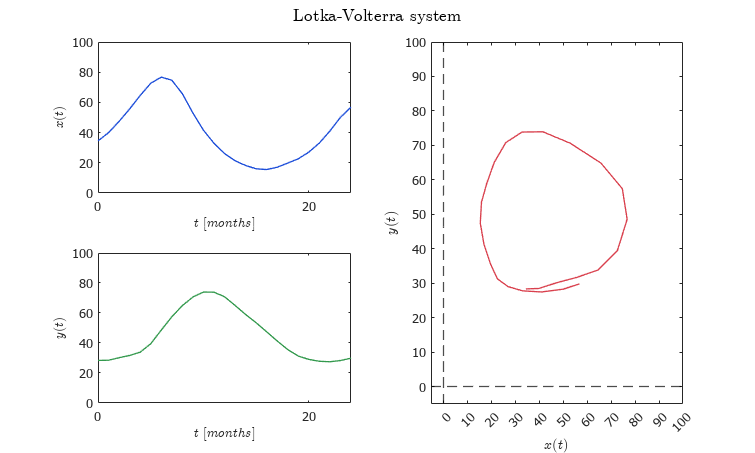

xo = smoothdata(xo,'gaussian',5);
yo = smoothdata(yo,'gaussian',5);
plotEDOsfit(to,xo,yo,P,0); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf, 'data fitting Lotka-Volterra.pdf','ContentType','vector')

## Fit data

P0 = [1;0.01;0.01;0.1];
mdl = variant(to,xo,yo,P0);


Sample size (n): 25
Parameters to be estimated (pars): 4
Degrees of freedom: 46
Significance level (alpha): 0.05
t-Student values: 2.0129
Adjusted R-squared: 0.99291
Corrected AIC (n/pars < 40): 190.5535

    Parameters    Estimate         SE           MoE                 CI95               Pvalue  
    __________    _________    __________    __________    ______________________    __________

      alpha         0.42667     0.0070761      0.014243      0.41243      0.44092    1.9713e-45
      beta        0.0089198    0.00017531    0.00035289    0.0085669    0.0092727    4.3521e-42
      delta       0.0052772    0.00010214    0.00020559    0.0050716    0.0054828    2.1722e-42
      gamma         0.21733     0.0043236      0.008703      0.20863      0.22603    7.5276e-42



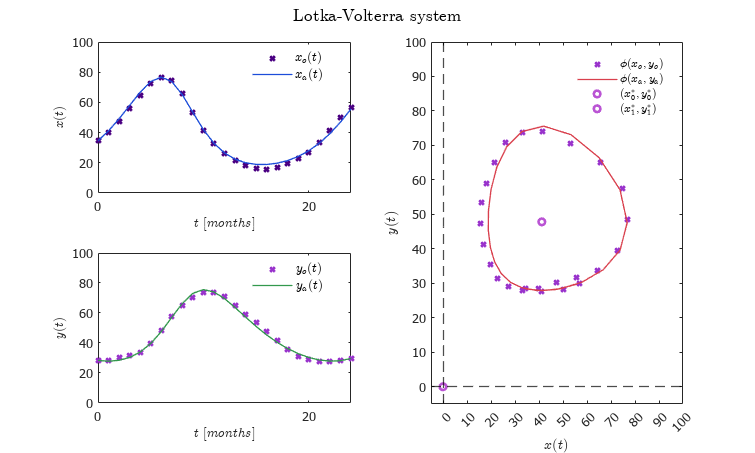

fa = mdl.Fitted;
fx = reshape(fa,[],2);
xa = fx(:,1); ya = fx(:,2);
P = table2array(mdl.Coefficients(:,1));
plotResults(to,[xo,xa],[yo,ya],P); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf, 'Lotka-Volterra (fitted).pdf','ContentType','vector')

## Experimental data for Fox-Rabbits system

## Data fitting

clc; clear; close all

## Raw data

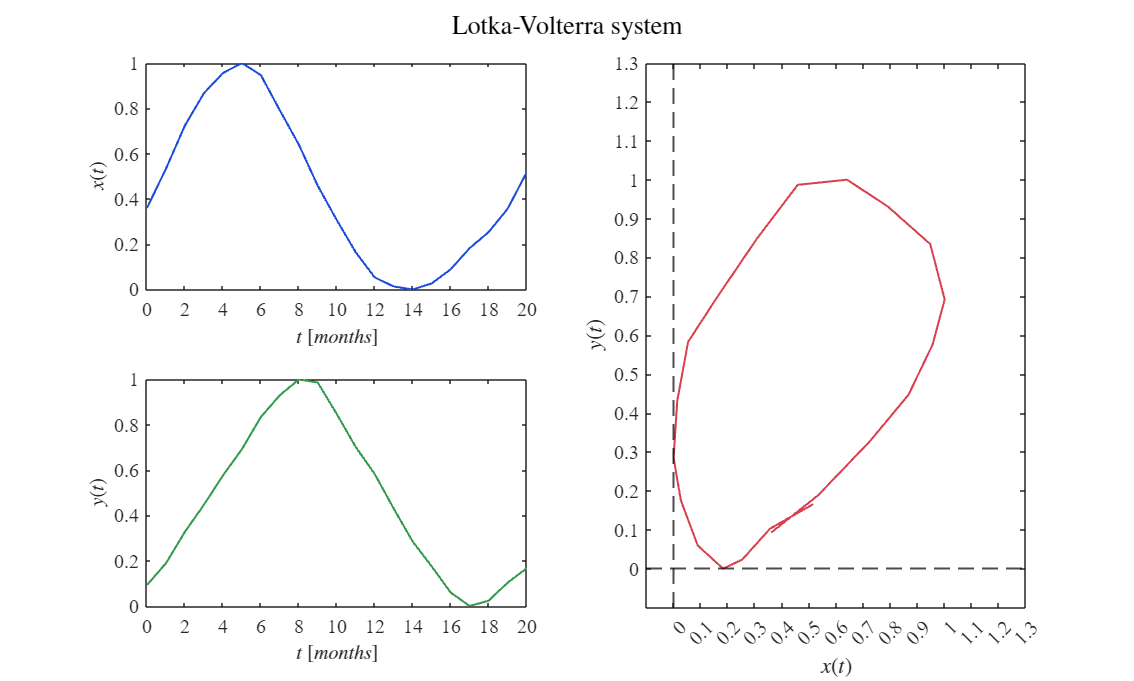

sys = readmatrix('ownData.csv');
to = sys(:,1); xo = sys(:,2); yo = sys(:,3);
xo = (xo - min(xo)) / (max(xo) - min(xo));
yo = (yo - min(yo)) / (max(yo) - min(yo));

alpha = 0.5; beta = 0.01; delta = 0.001; gamma = 0.2;
P = [alpha,beta,delta,gamma];
plotEDOsfit(to,xo,yo,P,0); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf, 'OD_Raw Data Lotka-Volterra.pdf','ContentType','vector')

## Smooth data

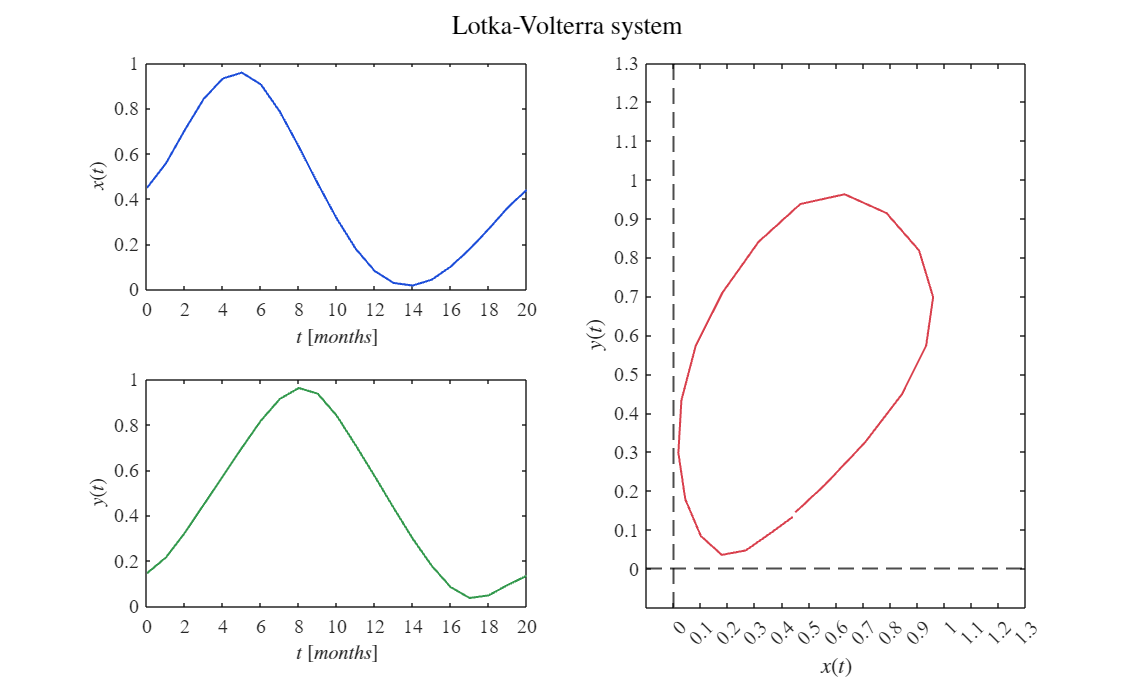

xo = smoothdata(xo,'gaussian',5);
yo = smoothdata(yo,'gaussian',5);
plotEDOsfit(to,xo,yo,P,0); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf, 'OD_data fitting Lotka-Volterra.pdf','ContentType','vector')

## Fit data

P0 = [1;0.01;0.01;0.1];
mdl = variant(to,xo,yo,P0);


Sample size (n): 21
Parameters to be estimated (pars): 4
Degrees of freedom: 38
Significance level (alpha): 0.05
t-Student values: 2.0244
Adjusted R-squared: 0.88911
Corrected AIC (n/pars < 40): -64.1005

    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      alpha       0.33269     0.025285    0.051186     0.2815    0.38388    9.9864e-16
      beta        0.73829     0.068269      0.1382    0.60009    0.87649    3.7072e-13
      delta       0.77015     0.064001     0.12956    0.64058    0.89971    1.5676e-14
      gamma        0.3364     0.030687    0.062122    0.27427    0.39852    2.4998e-13



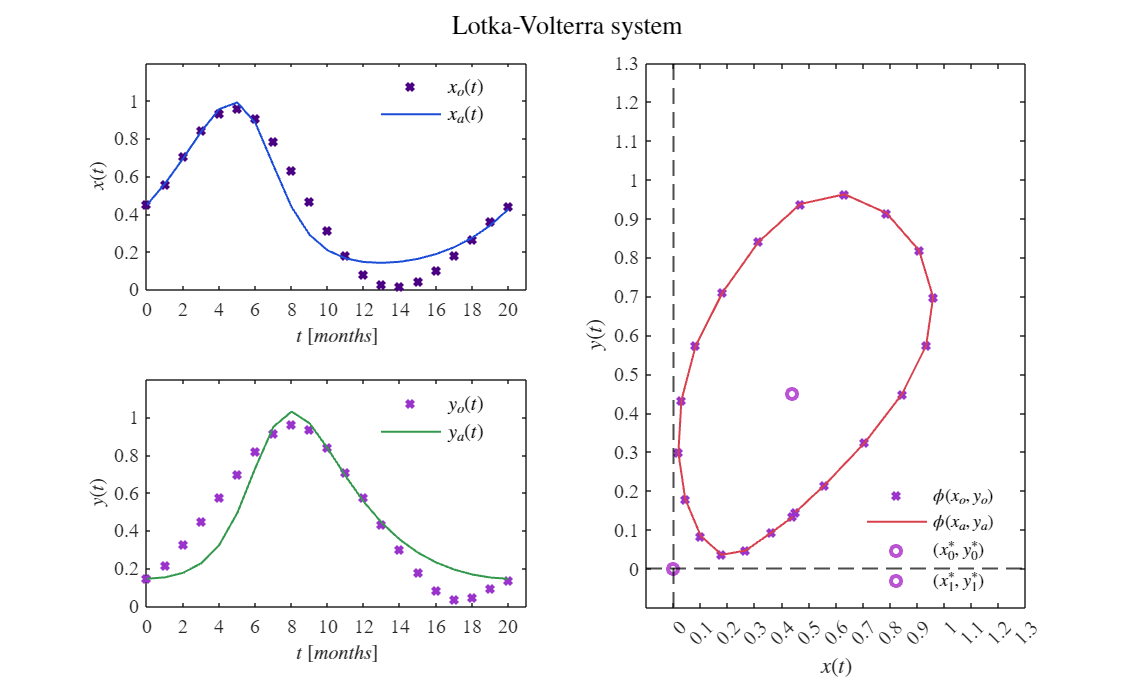

fa = mdl.Fitted;
fx = reshape(fa,[],2);
xa = fx(:,1); ya = fx(:,2);
P = table2array(mdl.Coefficients(:,1));
plotOwnResults(to,[xo,xa],[yo,ya],P); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf, 'OD_Lotka-Volterra (fitted).pdf','ContentType','vector')

## Functions

### Euler's method

function [t,x,y] = sys_Euler(x0,y0,dt,tend,P)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    n = round(tend/dt);
    t = (0:dt:tend);
    x = zeros(length(t),1); x(1) = x0;
    y = zeros(length(t),1); y(1) = y0;

    for i = 1:n
        x(i+1) = x(i) + (alpha*x(i) - beta*x(i)*y(i))*dt;
        y(i+1) = y(i) + (delta*x(i)*y(i) - gamma*y(i))*dt;
    end
end

### Heun's method


function [t,x,y] = sys_Heun(x0,y0,dt,tend,P)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    n = round(tend/dt);
    t = (0:dt:tend)';
    x = zeros(length(t),1); x(1) = x0;
    y = zeros(length(t),1); y(1) = y0;

    for i = 1:n
        [fx,fy] = f(x(i),y(i));
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt;
        [fxn,fyn] = f(xn,yn);

        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;
    end

    function [dx,dy] = f(x,y)
        dx = alpha*x-beta*x*y;
        dy = delta*x*y-gamma*y;
    end
end

### Solutions and trajectories

function plotEDOs(t,x,y,P,dt)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    c1 = [0.11, 0.30, 0.85]; c2 = [0.20, 0.60, 0.30];
    c3 = [0.85, 0.25, 0.30]; c4 = [0.95, 0.80, 0.20]; 
    m1 = [0.29, 0.00, 0.51]; m2 = [0.60, 0.20, 0.80];
    m3 = [0.73, 0.33, 0.83];

    subplot(2,2,1)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',c1)
    xlabel('$t$ $[months]$','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 600]); xticks(0:100:600)

    subplot(2,2,3)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[months]$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 100]); xticks(0:20:100)

    subplot(2,2,[2,4])
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(x,y,'-','LineWidth',1,'Color',c3)
    plot(x(1),y(1),'o','MarkerSize',5,'LineWidth',2,'Color',m1)
    plot(0,0,'x','MarkerSize',5,'LineWidth',2,'Color',m2)
    plot(gamma/delta,alpha/beta,'x','MarkerSize',5,'LineWidth',2,'Color',m3)
    xlabel('$x(t)$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([-60 600]); xticks(0:100:600)
    ylim([-5 100]); xticks(0:100:600)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    L = legend('$\phi(x,y)$','$(x(0),y(0))$','$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$');
    set(L,'Interpreter','latex','Location','none','Position',[0.778,0.263,0.115,0.041],'Box','off')
    
    if dt == 0
        ttl = 'Lotka-Volterra system';
        sgtitle(ttl,'Interpreter','latex')
    else
        ttl = ['Step size [dt]: ',num2str(dt)];
        sgtitle(ttl,'Interpreter','latex')
    end
end


### data fitting

function plotEDOsfit(t,x,y,P,dt)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    c1 = [0.11, 0.30, 0.85]; c2 = [0.20, 0.60, 0.30];
    c3 = [0.85, 0.25, 0.30]; c4 = [0.95, 0.80, 0.20]; 
    m1 = [0.29, 0.00, 0.51]; m2 = [0.60, 0.20, 0.80];
    m3 = [0.73, 0.33, 0.83];

    subplot(2,2,1)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',c1)
    xlabel('$t$ $[months]$','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    xlim([0 20]); xticks(0:2:20)
    ylim([0 1]); yticks(0:0.2:1)

    subplot(2,2,3)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[months]$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([0 20]); xticks(0:2:20)
    ylim([0 1]); yticks(0:0.2:1)

    subplot(2,2,[2,4])
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(x,y,'-','LineWidth',1,'Color',c3)
    % plot(x(1),y(1),'o','MarkerSize',5,'LineWidth',2,'Color',m1)
    % plot(0,0,'x','MarkerSize',5,'LineWidth',2,'Color',m2)
    % plot(gamma/delta,alpha/beta,'x','MarkerSize',5,'LineWidth',2,'Color',m3)
    xlabel('$x(t)$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([-0.1 1.3]); xticks(0:0.1:1.3)
    ylim([-0.1 1.3]); yticks(0:0.1:1.3)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    % L = legend('$\phi(x,y)$','$(x(0),y(0))$','$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$');
    % set(L,'Interpreter','latex','Location','none','Position',[0.778,0.263,0.115,0.041],'Box','off')
    
    if dt == 0
        ttl = 'Lotka-Volterra system';
        sgtitle(ttl,'Interpreter','latex')
    else
        ttl = ['Step size [dt]: ',num2str(dt)];
        sgtitle(ttl,'Interpreter','latex')
    end
end

### nonlinear regression algorithm

function mdl = variant(to,xo,yo,P0)
    x0 = xo(1); y0 = yo(1);
    to = [to;to];
    fo = [xo;yo];

    function fi = model(P,t)
        alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
        dt = 1E-1;
        t = reshape(t,[],2); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = x0;
        y = zeros(length(time),1); y(1) = y0;
        
        for i = 1:n
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);
    
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end
    
        function [dx,dy] = f(x,y)
            dx = alpha*x-beta*x*y;
            dy = delta*x*y-gamma*y;
        end

        xi = zeros(length(t),1);
        yi = zeros(length(t),1);
        
        for j = 1:length(t)
            k = abs(time - t(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
        end
        fi = [xi;yi];
    end
    
    mdl = fitnlm(to,fo,@model,P0);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['alpha';'beta ';'delta';'gamma'];
    Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
    
    fprintf(['\nSample size (n): ', num2str(numel(xo))])
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student values: ', num2str(tval)])
    fprintf(['\nAdjusted R-squared: ', num2str(mdl.Rsquared.Adjusted)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])

    disp(Results)
end

### Plot Results

function plotResults(t,x,y,P)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    c1 = [0.11, 0.30, 0.85]; c2 = [0.20, 0.60, 0.30];
    c3 = [0.85, 0.25, 0.30]; c4 = [0.95, 0.80, 0.20]; 
    m1 = [0.29, 0.00, 0.51]; m2 = [0.60, 0.20, 0.80];
    m3 = [0.73, 0.33, 0.83];

    subplot(2,2,1)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',2,'Color',m1)
    plot(t,x(:,2),'-','LineWidth',1,'Color',c1)
    xlabel('$t$ $[months]$','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    L = legend('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','off')
    xlim([0 24]); xticks(0:1:24)
    ylim([0 100]); xticks(0:20:100)

    subplot(2,2,3)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',2,'Color',m2)
    plot(t,y(:,2),'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[months]$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    L = legend('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','off')
    xlim([0 24]); xticks(0:1:24)
    ylim([0 100]); xticks(0:20:100)

    subplot(2,2,[2,4])
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(x(:,1),y(:,1),'x','MarkerSize',5,'LineWidth',2,'Color',m2)
    plot(x(:,2),y(:,2),'-','LineWidth',1,'Color',c3)
    plot(0,0,'o','MarkerSize',5,'LineWidth',2,'Color',m3)
    plot(gamma/delta,alpha/beta,'o','MarkerSize',5,'LineWidth',2,'Color',m3)
    xlabel('$x(t)$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([-5 100]); xticks(0:10:100)
    ylim([-5 100]); xticks(0:10:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    L = legend('$\phi(x_o,y_o)$','$\phi(x_a,y_a)$','$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$');
    set(L,'Interpreter','latex','Location','Best','Box','off')
end

### Plot Own Results

function plotOwnResults(t,x,y,P)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    c1 = [0.11, 0.30, 0.85]; c2 = [0.20, 0.60, 0.30];
    c3 = [0.85, 0.25, 0.30]; c4 = [0.95, 0.80, 0.20]; 
    m1 = [0.29, 0.00, 0.51]; m2 = [0.60, 0.20, 0.80];
    m3 = [0.73, 0.33, 0.83];

    subplot(2,2,1)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',2,'Color',m1)
    plot(t,x(:,2),'-','LineWidth',1,'Color',c1)
    xlabel('$t$ $[months]$','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    L = legend('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','off')
    xlim([0 21]); xticks(0:2:21)
    ylim([0 1.2]); yticks(0:0.2:1)

    subplot(2,2,3)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',2,'Color',m2)
    plot(t,y(:,2),'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[months]$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    L = legend('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','off')
    xlim([0 21]); xticks(0:2:21)
    ylim([0 1.2]); yticks(0:0.2:1)

    subplot(2,2,[2,4])
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(x(:,1),y(:,1),'x','MarkerSize',5,'LineWidth',2,'Color',m2)
    plot(x(:,2),y(:,2),'-','LineWidth',1,'Color',c3)
    plot(0,0,'o','MarkerSize',5,'LineWidth',2,'Color',m3)
    plot(gamma/delta,alpha/beta,'o','MarkerSize',5,'LineWidth',2,'Color',m3)
    xlabel('$x(t)$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([-0.1 1.3]); xticks(0:0.1:1.3)
    ylim([-0.1 1.3]); yticks(0:0.1:1.3)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    L = legend('$\phi(x_o,y_o)$','$\phi(x_a,y_a)$','$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$');
    set(L,'Interpreter','latex','Location','Best','Box','off')
end
